## **Forward TRF example**

This live script example is an adaptation of the forward TRF example presented at the Cognition and Natural Sensory Processing (CNSP) Workshop 2022. Please see [https://cnspworkshop.net](https://cnspworkshop.net) for tutorials, videotutorials, datasets, and additional resources)

This example script loads and preprocesses a publicly available electroencephalography (EEG) dataset (the diliBach dataset, [https://doi.org/10.7554/eLife.51784,](https://doi.org/10.7554/eLife.51784,) [https://datadryad.org/stash/dataset/doi:10.5061/dryad.g1jwstqmh](https://datadryad.org/stash/dataset/doi:10.5061/dryad.g1jwstqmh)). The same script can be applied to other datasets (see the list of datasets here: [https://cnspworkshop.net/resources.html).](https://cnspworkshop.net/resources.html).) EEG signals were recorded as participants listened to monophonic Bach melodies.

'dataStim.mat' contains the stimulus features. 'pre_dataSub1.mat' contains the preprocessed EEG signals (see [https://pubmed.ncbi.nlm.nih.gov/37744463/](https://pubmed.ncbi.nlm.nih.gov/37744463/)). Then, the script runs a typical forward TRF analysis to measure how strongly the EEG signals encode specific stimulus features, such as the sound envelope and the note onsets.

Author: Giovanni M. Di Liberto

### Workspace setup

This section clears the workspace and adds the library folders to the Matlab paths

clear all
close all

addpath ./libs/cnsp_utils
addpath ./libs/cnsp_utils/cnd
addpath ../mtrf
addpath ./libs/fileDownload

### Data preparation

This section downloads the sample data. This sample dataset consists of 64-channel EEG time-series from two distinct individuals (pre_dataSub files; note that the original dataset includes data from 20 participants). The signals were filtered between 1 and 8 Hz and downsampled to 64Hz. The dataStim.mat file contains features of the corresponding music stimulus (i.e., Hilbert envelope and note onsets). dataStim is the input of a forward mTRF model. dataSub is the output of a forward mTRF model.

dataStim_URL = "https://www.data.cnspworkshop.net/sampleData/diliBach/dataStim.mat";
dataSub1_URL = "https://www.data.cnspworkshop.net/sampleData/diliBach/pre_dataSub1.mat";
dataSub2_URL = "https://www.data.cnspworkshop.net/sampleData/diliBach/pre_dataSub2.mat";

stimFilename = "dataStim.mat";
eegFilenames = {'pre_dataSub1.mat','pre_dataSub2.mat'};

if ~isfile(stimFilename)
    downloadFile("dataStim.mat", dataStim_URL, ShowFilename=true)
else
    disp('Skipping download. Stim file already present.')
end

Skipping download. Stim file already present.



if ~isfile(eegFilenames{1})
    downloadFile(eegFilenames{1}, dataSub1_URL, ShowFilename=true)
else
    disp('Skipping download. EEG file already present.')
end

Skipping download. EEG file already present.



if ~isfile(eegFilenames{2})
    downloadFile(eegFilenames{2}, dataSub2_URL, ShowFilename=true)
else
    disp('Skipping download. EEG file already present.')
end

Skipping download. EEG file already present.



nSubs = length(eegFilenames);

### Forward mTRF model fit

Setting up mTRF hyperparameters

tmin = -200

tmin = -200

tmax = 600

tmax = 600

lambdas = 10.^(-4:2:4); % small set of lambdas (quick)
% lambdas = 10.^(-6:1:6); % larger set of lambdas (slower)
dirTRF = 1; % Forward TRF model
stimIdx = 2; % Stimulus feature to use in the model fit

if tmin > tmax
    disp('Warning: tmin > tmax; setting tmax=tmin for the analysis')
    tmax = tmin;
end

Loading Stimulus data

stimFilename = 'dataStim.mat';
disp('Loading stimulus data')

Loading stimulus data


load(stimFilename,'stim')

stim = cndNormalise(stim);

Loading EEG data

subIdx = 1;
eegFilename = eegFilenames{subIdx}; 
disp(['Loading preprocessed EEG data: ',eegFilename])

Loading preprocessed EEG data: pre_dataSub1.mat


load(eegFilename,'eeg')

eeg = cndNormalise(eeg); % Standardise neural data (preserving the ratio between channels)

Making sure that stim and neural data have the same length. The trial may end a few seconds after the end of the audio e.g., the neural data may include the break between trials. It would be best to do this chunking at preprocessing, but let's check here, just to be sure. The function returnes a version of stim and eeg where their lengths have been made equal by cutting the tail of the longer time-series where necessary.

[stim,eeg] = cndCheckStimNeural(stim,eeg);

Forward TRF (unregularised)

disp('Running mTRFtrain')

Running mTRFtrain


model = mTRFtrain(stim.data(stimIdx,:),eeg.data,eeg.fs,dirTRF,tmin,tmax,0,'verbose',0);    


Plot TRF weights

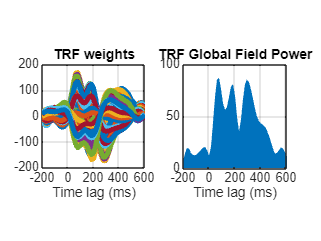

figure;
subplot(1,2,1)
mTRFplot(model,'trf');
title('TRF weights')
grid on

% Plot GFP
subplot(1,2,2)
mTRFplot(model,'gfp',[],'all');
title('TRF Global Field Power')
grid on

### Model tuning

Determine optimal lambda

disp('Running mTRFcrossval')
[stats,t] = mTRFcrossval(stim.data(stimIdx,:),eeg.data,eeg.fs,dirTRF,tmin,tmax,lambdas,'verbose',0);
    
% Calculating optimal lambda. Display and store results
[maxR,bestLambda] = max(squeeze(mean(mean(stats.r,1),3)));
disp(['r = ',num2str(maxR)])
rAll(subIdx) = maxR;
rAllElec(:,subIdx) = squeeze(mean(stats.r(:,bestLambda,:),1));
disp(['Mean r = ',num2str(mean(rAll))])

% Fit TRF model with optimal regularisation parameter
disp('Running mTRFtrain')
model = mTRFtrain(stim.data(stimIdx,:),eeg.data,eeg.fs,dirTRF,tmin,tmax,lambdas(bestLambda),'verbose',0);

% Store TRF model
modelAll(subIdx) = model;


Plot TRF weights of fine-tuned model

figure;
subplot(1,2,1)
mTRFplot(model,'trf');
title('TRF weights')
grid on

% Plot GFP
subplot(1,2,2)
mTRFplot(model,'gfp',[],'all');
title('TRF Global Field Power')
grid on


### Combining data from multiple subjects

Loading EEG data for participant 2. Note that all this is typically run with for loops. As an example, we have unpacked the loops here. The code that follows is largely the same as what was run for participant 1 above.

subIdx = 2;
eegFilename = eegFilenames{subIdx}; 
disp(['Loading preprocessed EEG data: ',eegFilename])

Loading preprocessed EEG data: pre_dataSub2.mat


load(eegFilename,'eeg')

eeg = cndNormalise(eeg); % Standardise neural data (preserving the ratio between channels)

Making sure that stim and neural data have the same length.

[stim,eeg] = cndCheckStimNeural(stim,eeg);

Determine optimal lambda

disp('Running mTRFcrossval for participant 2')

Running mTRFcrossval for participant 2


[stats,t] = mTRFcrossval(stim.data(stimIdx,:),eeg.data,eeg.fs,dirTRF,tmin,tmax,lambdas,'verbose',0);
    
% Calculating optimal lambda. Display and store results
[maxR,bestLambda] = max(squeeze(mean(mean(stats.r,1),3)));
disp(['r = ',num2str(maxR)])

r = 0.0048994


rAll(subIdx) = maxR;
rAllElec(:,subIdx) = squeeze(mean(stats.r(:,bestLambda,:),1));
disp(['Mean r = ',num2str(mean(rAll))])

Mean r = 0.0024497



% Fit TRF model with optimal regularisation parameter
disp('Running mTRFtrain for participant 2')

Running mTRFtrain for participant 2


model = mTRFtrain(stim.data(stimIdx,:),eeg.data,eeg.fs,dirTRF,tmin,tmax,lambdas(bestLambda),'verbose',0);

% Store TRF model
modelAll(subIdx) = model;


Plot TRF weights of fine-tuned model

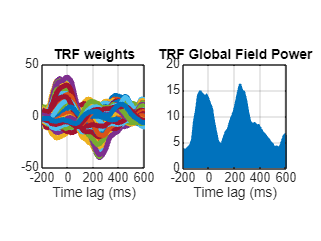

figure;
subplot(1,2,1)
mTRFplot(model,'trf');
title('TRF weights')
grid on

% Plot GFP
subplot(1,2,2)
mTRFplot(model,'gfp',[],'all');
title('TRF Global Field Power')
grid on

Combine participants 1 and 2, and then plot the average TRF weights of fine-tuned models

plotNormFlag = true;
avgModel = mTRFmodelAvg(modelAll,plotNormFlag);

Error using  + 
Arrays have incompatible sizes for this operation.

Error in mTRFmodelAvg (line 31)
        wAvg = wAvg + w;

Related documentation


figure;
subplot(1,2,1)
mTRFplot(avgModel,'trf');
title('TRF weights')
grid on

% Plot GFP
subplot(1,2,2)
mTRFplot(avgModel,'gfp',[],'all');
title('TRF Global Field Power')
grid on
